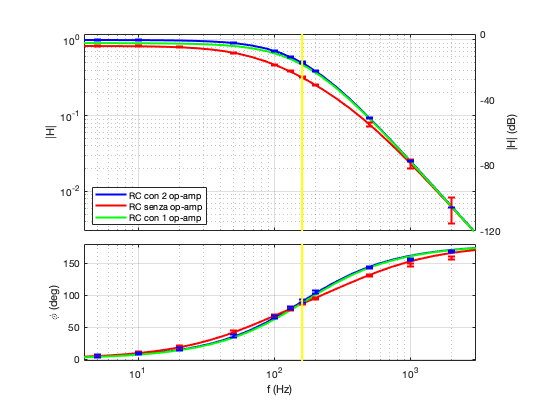

addpath("routine/");clear;clc
R=1e5; C=1e-8;
tau=R*C;
f3dB=1/(2*pi*tau);
R_osc=1e6; C_osc=120e-12;

%funzioni
H    = @(V_in, V_out)   V_out./V_in;
phi  = @(dt,f)          dt .* f*2*pi;
dH   = @(V_in,V_out,dV_in, dV_out,H) H.*sqrt((dV_in./V_in).^2 + (dV_out./V_out).^2);
dphi = @(f)          ones(size(f))*2*pi/180;

f_exp  = [5    10    20    50    100    130    160    200    500    1e3    2e3]';
%dati 2 op-amp
V_in   = [3    3     3     2.98  3      2.99   2.98   3      3      3      3]';
dV_in  = [37.5 37    37.5  50    40     43     43     43     31     43     43]'*0.5e-3;
V_out  = [3    3     2.96  2.73  2.15   1.8    1.5    1.17   0.282  0.0757 0.0185]';
dV_out = [43   56    43    50    56     43     56     22     10     0.0095 0.01]'*0.5e-3;
dt     = [2.7  2.36  2.18  2     1.82   1.7    1.58   1.46   0.796  0.432  0.234]'*1e-3;

H1    = H(V_in,V_out);
phi1  = phi(dt,f_exp);
dH1   = dH(V_in,V_out,dV_in,dV_out,H1);
dphi1 = dphi(f_exp);
%dati senza op-amp
V_in   = [3    3     3     2.98  3      2.99   2.98   3      3      3      3]';
dV_in  = [37.5 37    37.5  50    40     43     43     43     31     43     43]'*0.5e-3;
V_out  = [2.48 2.48  2.4   2.03  1.42   1.16   .962   .77    .231   .07    .0183]';
dV_out = [50   50    50    43    30     30     30     30     30     20     14]'*0.5e-3;
dt     = [3    2.82  2.6   2.34  1.86   1.66   1.51   1.32   .726   .408   .22]'*1e-3;

H2    = H(V_in,V_out);
phi2  = phi(dt,f_exp);
dH2   = dH(V_in,V_out,dV_in,dV_out,H2);
dphi2 = dphi(f_exp);
%modello
f=logspace(0,5)';
w=2*pi*f;

%due op-amp
G1 = 1./((1 - 1i*w*tau).^2);
%senza op-amp
Z_eq = R./(1-1i*w*tau);
Z    = R_osc./(1-1i*w*R_osc*(C+C_osc));
G2   = Z.*Z_eq./(R*(Z_eq+R+Z));
%un op-amp
G3 = (1./(1-1i*w*tau)).*(Z./(Z+R));

fig_modelli = bode_plot(f,G3,'col','g','add_dB','fig', bode_plot(f,G2,'col','r','fig', bode_plot(f,G1,'col','b')));

fig1 = bode_plot(f_exp,[H1 phi1],'err',[dH1 dphi1],'points','none','col','b','fig', bode_plot(f_exp,[H2 phi2],'col','r','err',[dH2 dphi2],'points','none', 'fig', fig_modelli));

fig = bode_plot([f3dB f3dB], [[1e-3 10]' [-10 190]'],'col','y','fig',fig1);
figure(fig(1)); axes(fig(2))
ylim([3e-3, 1.2]);    xlim([4, 3e3])
legend({'RC con 2 op-amp','RC senza op-amp','RC con 1 op-amp'}, "Location","best")
axes(fig(3));
ylim([-3, 180]);       xlim([4, 3e3])